# A Gentle Introduction to MATLAB

## 1. Goal of this chapter

- A short history of MATLAB

- Exposure to the MATLAB environment

- Become familiar with the basic functionality of MATLAB

- Basic mathematical operations

- Basic graphics and visualization

## 2. Purpose of MATLAB

MATLAB is a high-performance programming environment for numerical and technical applications.

- High-level programming language

- We use an IDE (interactive development environment) to interact with it

Widely used in scientific community, de facto programming languiage in academia.

- Numerical computations

- Data analysis and visualization

- Data acquisition

- Hardware configuration and control

- Statistical analysis

- Application development and deployment

- AI and Machine Learning

- (Used in virtually any engineering domain)

But, what is MATLAB?

- **MAT**rix **LAB**oratory

- The first version was created by **Cleve Moler **at the University of New Mexico in the 1970s

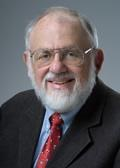

- Written in FORTRAN, with matrix is the only data type

- "The first MATLAB® was not a programming language; it was a **simple interactive matrix calculator**. There were no programs, no toolboxes, no graphics. And no ODEs or FFTs." (Cleve Moler, MathWorks Inc.)

- There were only 71 functions and reserved words in the frist version

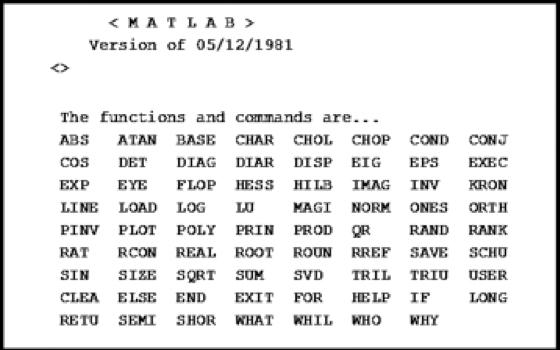

- Now there are thousands of functions and libraries, and hundreds of toolboxes

- A toolbox is a collection of libraries that specilaize on a certain task, e.g., Signal Processing Toolbox, Deep Learning Toolbox, Curve Fitting Toolbox, Parallel Computing Toolbox, etc. Each toolbox is licensed seperately

- [MATLAB Documentation](https://www.mathworks.com/help/matlab/) is extremely powerful and easy to use

- The user community is vast. Share custom-written scripts or answer questions in [MATLAB Central](https://www.mathworks.com/matlabcentral/) website

## 3.Getting Started

Getting help:

help max    % Shows content in the comman window

 max    Largest component.
    For vectors, max(X) is the largest element in X. For matrices,
    max(X) is a row vector containing the maximum element from each
    column. For N-D arrays, max(X) operates along the first
    non-singleton dimension.
 
    [Y,I] = max(X) returns the indices of the maximum values in vector I.
    If the values along the first non-singleton dimension contain more
    than one maximal element, the index of the first one is returned.
 
    max(X,Y) returns an array with the largest elements taken from X or Y.
    X and Y must have compatible sizes. In the simplest cases, they can be
    the same size or one can be a scalar. Two inputs have compatible sizes
    if, for every dimension, the dimension sizes of the inputs are either
    the same or one of them is 1.
 
    [Y,I] = max(X,[],DIM) operates along the dimension DIM. 
 
    When X is

doc max    % Opens a seperate window

Accessing inside a function or script:

edit max    % Warning! Don't modify the built-in functions! (Probably you can't anyway)

To clear the workspace:

clear

To close all open figure windows:

close all

To clear the command window:

clc

To stop execution: (demo infinite loop)

    press Ctrl + C

## 4. MATLAB as a Calculator

**Elementary mathematical operations.**

Addition:

2 + 3

ans = 5

Substraction:

8 - 3

ans = 5

Multiplication:

14 * 8

ans = 112

Division:

31 / 4  % Number of spaces doesn't matter

ans = 7.7500

More complex statements can be written:

2 + 3 + 4 - 7*5 + 8/9 + 1 - 5*6/3

ans = -34.1111

Parantheses to avoid disambiguities:

5 + 3*8

ans = 29

(5 + 3)*8

ans = 64

**Advanced mathematical operations.**

Power: x to the power of p:

2^3

ans = 8

Natural logarithm:

log(2.71828)

ans = 1.0000


log(1)

ans = 0

Exponential:

exp(1)

ans = 2.7183

Let's verify this equation numerically:

## 
$$e^{\left(log\left(x\right)+log\left(y\right)\right)} =x\ast y$$


6 * 7

ans = 42


exp(log(6) + log(7))

ans = 42.0000

Trigonometric functions:

sin(0)

ans = 0


sin(pi/2)

ans = 1


cos(pi/2)

ans = 6.1232e-17

What is the deal with the e? It means "10 to the power":

1e1

ans = 10


2e3

ans = 2000


5e-2

ans = 0.0500

## 5.Assignments

Assigning "values" to "variables":

a = 10 

a = 10


% a is a variable, and number 10 is assigned to a.
% We use the "=" operator.
% Now variable a is in the memory. It can later be used, modified, or deleted.

b = 8

b = 8


c = a + b*2

c = 26

## 6.Defining Matrices

MATLAB is an efficent computational tool because it can work with matrices and vectors.

A simple vector can be defined as follows:

[1 2 3]

ans =      1     2     3


A simple matrix can be created as:

[6 7 8; 10 11 12]

ans =      6     7     8
    10    11    12


All rows should have the equal number of elements:

[6 7 8; 10 11] % This generates an error

Dimensions of matrices being concatenated are not consistent.

Assigning a matrix to a variable:

a = [1 2 3 4 5]

a =      1     2     3     4     5


b = [6 7 8]

b =      6     7     8


*Note:** Variables are case sensitive. ****a**** and ****A**** are not the same thing!*

A + b

Undefined function or variable 'A'.

Some commonly used matrices can be created by using special functions:

Identity matrix:

eye(5)

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


Matrix with all 1's:

ones(3)

ans =      1     1     1
     1     1     1
     1     1     1


Matrix with all 0's:

zeros(4,7)

ans =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


Matrix with random numbers:

rand(5,2)

ans =     0.8147    0.0975
    0.9058    0.2785
    0.1270    0.5469
    0.9134    0.9575
    0.6324    0.9649


Let's see what is in the workspace:

who


Your variables are:

a    ans  b    c    s    



More details:

whos

  Name      Size            Bytes  Class     Attributes

  a         1x5                40  double              
  ans       5x2                80  double              
  b         1x3                24  double              
  c         1x1                 8  double              
  s         1x4                 8  char                



## More on matrices

a = rand(10,5)

a =     0.1576    0.6557    0.7060    0.4387    0.2760
    0.9706    0.0357    0.0318    0.3816    0.6797
    0.9572    0.8491    0.2769    0.7655    0.6551
    0.4854    0.9340    0.0462    0.7952    0.1626
    0.8003    0.6787    0.0971    0.1869    0.1190
    0.1419    0.7577    0.8235    0.4898    0.4984
    0.4218    0.7431    0.6948    0.4456    0.9597
    0.9157    0.3922    0.3171    0.6463    0.3404
    0.7922    0.6555    0.9502    0.7094    0.5853
    0.9595    0.1712    0.0344    0.7547    0.2238


Matrix dimensions:

size(a)

ans =     10     5


length(a)

ans = 10

size(a,1)

ans = 10

size(a,2)

ans = 5

A vector is a 1-dimensional matrix:

v = 5:20

v =      5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


size(v)

ans =      1    16


We can specify a step size:

v = 0:2:10

v =      0     2     4     6     8    10


A very convenient function to generate vectors is ***linspace(a, b, n)***:

v = linspace(1,10,20)

v =     1.0000    1.4737    1.9474    2.4211    2.8947    3.3684    3.8421    4.3158    4.7895    5.2632    5.7368    6.2105    6.6842    7.1579    7.6316    8.1053    8.5789    9.0526    9.5263   10.0000


Transposing a vector or matrix is quite simple:

v'

a = [1 2 3 4; 5 6 7 8]
b = a'

## Accessing matrix elements

First method: Using the indices *i* and *j*:

v(2)

b(3,2)

Second method: Slicing:

c = [1:10; 11:20; 21:30]'    % A 3by10 matrix    

Slice the second column:

c(:,2)

Slice the fifth row:

c(5,:)

Slice the upper half:

c(1:5,:)

Slice the bottom right, 4by2 matrix:

c(7:end,2:end)

## Exercise 1.1

Create a variable A using the matrix below:


$$\left\lbrack \begin{array}{c}
7 & 5\\
2 & 3\\
1 & 8
\end{array}\right\rbrack$$


Change the element in 1st row, 2nd column to a number twice its original value.

Take the transpose of the final matrix and assign it to variable B.

Display B.

% Code here...

## 7.Basic Matrix Algebra

Addition:

p = [1 2; 3 4]

p + 2


$$\left\lbrack \begin{array}{c}
1 & 2\\
3 & 4
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
2 & 2\\
2 & 2
\end{array}\right\rbrack$$


Element-wise addition:

q = [6 7; 8 9]

p + q


$$\left\lbrack \begin{array}{c}
1 & 2\\
3 & 4
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
6 & 7\\
8 & 9
\end{array}\right\rbrack$$


*Note:** Matrices must have the same number of rows and columns for element-wise addtion to work!*

Same applies to the other basic mathematical operations, such as division:

q/2

Element-wise division and multiplication:

q./p

q.*p

p.^3

Consider the following system of linear equations:


$$\begin{array}{l}
\text{\,}\text{\,}\text{\,}x+\text{\,}\text{\,}\text{\,}y+2z=9\\
2x+4y-3z=1\\
3x+6y-5z=0
\end{array}$$


We can solve this by hand (the long way) or using MATLAB (the short way):


$$\left\lbrack \begin{array}{c}
1 & 1 & 2\\
2 & 4 & -3\\
3 & 6 & -5
\end{array}\right\rbrack \ast \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
9\\
1\\
0
\end{array}\right\rbrack$$


A = [1 1 2; 2 4 -3; 3 6 -5]

B = [9; 1; 0]

X = linsolve(A,B)

## Exercise 1.2

Solve the following equation for t = 0.......100:


$$x=5t^{1\ldotp 7} +2$$


Print last 10 elements of vector x.

% Code here...

Clear the workspace:

clear

## 8.More on Indexing

Accessing individual elements:


$$\begin{array}{l}
A\left(i,j\right)\\
A\left(n\right)
\end{array}$$


Create a matrix A, and access element 7:


$$A=\left\lbrack \begin{array}{c}
1 & 2 & 3 & 4\\
5 & 6 & 7 & 8\\
10 & 20 & 30 & 40\\
50 & 60 & 70 & 80
\end{array}\right\rbrack$$


A = [1 2 3 4; 5 6 7 8; 10 20 30 40; 50 60 70 80]

A(2,3)

A(10)

Assign the number 23 to each entry in the first row:

A(1,:) = 23

Find indices that satisfy a specific creteria, such as >35:

find(A>35)

ind_to_change = find(A>35)

A(ind_to_change) = 0

find(A==20)
[r, c] = find(A==20)

## 9.Relational Operators

- <            Less than

- <=          Less than or equal to

- >            Greater than

- >=          Greater than or equal to

- ==          Equal to

- ~=          Not equal to

Examples:

A = [2 4 6; 8 10 12]
B = [5 5 5; 9 9 9]

A > 7

A < B

## 10.Logical Operators and Functions

- ~                Not

- &                And

- |                 Or

- any(x)        returns 1 if any element of x is a nonzero

- all(x)           retruns 1 if all elements are nonzero

- isnan(x)      returns 1 at each NaN location

- logical(x)     convert numeric values to logicals

Examples:

[1 0 0 0] & [0 0 1 1]

any([0 0 1 0 0 0 1])

all([0 0 1 0 0 0 1])

## 11.Conditional Structures

a = 7;
b = 7;

if a*b <= 50 && a*b > 0 
    fprintf('less than or equal to 50\n')
elseif a*b < 0
    fprintf('less than zero\n')
else
    fprintf('larger than 50\n')
end

## 12.Iterative Structures (Loops)

For loop:

for i=1:10
    fprintf(num2str(i*2));
end

Nested for loop:

a = 5;
b = 3;

M = [];
for i = 1:a
    for j = 1:b
        M(i,j) = 1/(i+j);
    end
end

disp(M);

While loop:

a = 10;

while a > 5
    fprintf(num2str(a));
    a = a - 1;
end

*Note:** For loops are slow! Use ****vectorization**** whenever it is possible!*

***Example:***


$$b\left(x\right)=\text{\,}\left\lbrace \begin{array}{c}
sin\left(\frac{x}{10}\right) & for\text{\,}x\text{\,}multiples\text{\,}of\text{\,}4\\
x^2  & otherwise
\end{array}\right.$$


tic

for x = 1:10000
    if mod(x,4) == 0
        b(x) = sin(x/10);
    else
        b(x) = x^2;
    end
end

toc

disp(b(1:10));

Alternatively:

tic

x = 1:10000;
ind1 = find(mod(x,4) == 0);
ind2 = find(mod(x,4) ~= 0);
b(ind1) = sin(ind1/10);
b(ind2) = ind2.^2;

toc

disp(b(1:10));

## 13.Graphics and Visualization

- Visualization of data and data structures is one of the great strengths of MATLAB

- Visualization is usually the first step in data analysis. The goal is examine the quality of the data and gain insights into the nexts steps to be taken

- It is also very useful in summarizing the process and presenting the results

## Basics

y = [0 4 7 9 4 8 3 6 8 4 5];

plot(y)

plot(y, '*')

x = 0:0.1:1;

plot(x, y)

plot(x, y, 'r')

Plot a sinusoid:

x = 0:0.1:10;
y = sin(x);
plot(x, y)

Plot multiple lines:

z = cos(x);
plot(x, y)
hold on
plot(x, z)

Beutify the plot:

plot(x, y); hold on; plot(x, z); hold off;
xlabel('time')
ylabel('magnitude')
title('sin(x) and cos(x)')
legend('sin(x)', 'cos(x)')

Bar plot:

results = [55 30 10 5];

bar(results)

Histogram:

numbers = [1 1 1 1 1 2 2 2 3 3 3 3 3 3 3 3 4 4 5];

histogram(numbers)

## Exercise 1.3

Simulate a normal (Gaussian) distribution using 10,000 random numbers and the **histogram** functions. Hint: use **randn** function.

% Code here

## Advance Plotting

- Subplots

- 3D figures

- Interactive plots, etc.

## Subplots: 

- A two-dimensional grid of plots

x = 0:0.1:10
figure
subplot(2,2,1); plot(x, sin(x)); title('sin(x)')
subplot(2,2,2); plot(x, cos(x)); title('cos(x)')
subplot(2,2,3); plot(x, sqrt(x)); title(' {\surd}x')
subplot(2,2,4); plot(x, exp(x)); title('e^x')

## Surface plot:

- Magnitude values are represented by colors:

y = [1 2 3 4 5;
     8 9 10 11 12;
     13 14 15 16 17;
     18 19 20 21 22];
disp(y)
figure
surface(y)     

## 3D Plots:

- Similar to 2D plots, with an extra dimension!

- Most common functions are **surf** and **mesh**

- They operate on a grid

- Magnitudes are represented by heights and colors 

A very handy function: **meshgrid**

clear
v = 0:.2:0.8

[X, Y] = meshgrid(v)

figure; hold on
plot(X,Y,'k');
plot(Y,X,'k')
plot(X,Y,'b.', 'MarkerSize', 30)
axis off

Example: Plot the following function in 3D using a meshgrid.

## 
$$f\left(x,y\right)=\text{\,}x^2 +y^2$$


x = 1.5;
y = 2;
z = x^2 + y^2;
disp(z)

x = -5:1:5;
y = 1;
z = x.^2 + y^2;
disp(z)

[X,Y] = meshgrid(x);
Z = X.^2 + Y.^2;
figure
mesh(Z)

x = -5:1:10;
[X,Y] = meshgrid(x);
Z = X.^2 + Y.^2;
figure
surf(Z)

close all